# Local contrast enhancement based on Undecimated Wavelet Transform

**alpha: intensity of enhancement**

**brightness: brightness added or reduced**

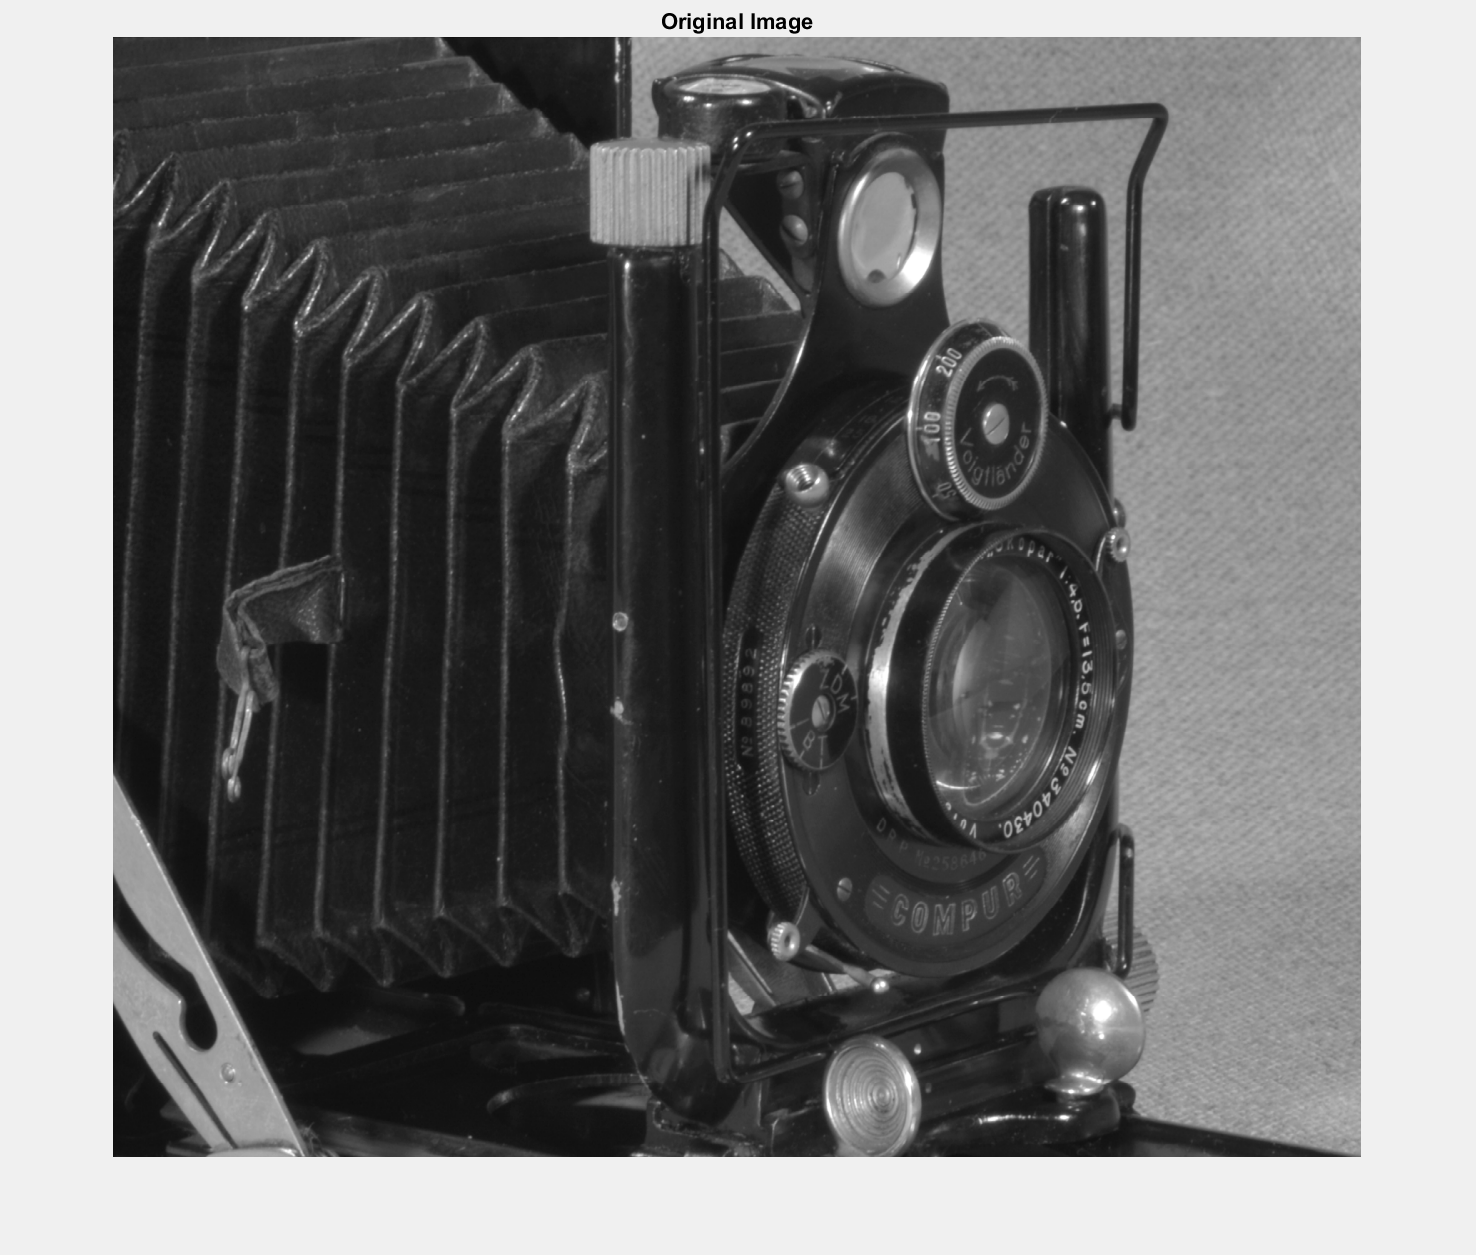

clear; clc; close all;


alpha = 2;
brightness = -5;
CLAHE = false;

file_path = 'E:\Image processing\Course project\Wavelet-Based Local Contrast Enhancement for Satellite, Aerial and Close Range Images\image2.bmp';

image_original = imread(file_path);
[h, w, ~] = size(image_original);
if ~CLAHE
    image = rgb2gray(image_original(1:h-mod(h,16), 1:w-mod(w,16), :));
else
    image = adapthisteq(rgb2gray(image_original(1:h-mod(h,16), 1:w-mod(w,16), :)));
end
image_denoised = wdenoise2(image, 'DenoisingMethod', 'SURE');

[A,H,V,D] = swt2(image_denoised,4,'haar');
cutoff = my_iswt2_second(A,H,V,D, 'haar');
my_sigma = cutoff./3;
g = [1 1 1 1].*[alpha alpha+1 alpha+0.5 alpha].* my_sigma .*2.5;

enhanced = my_iswt2(A,H,V,D, 'haar', my_sigma, g) + brightness;

fig1 = figure;
set(gcf,'Visible','on')
% fig1.Position(3:4) = [w, h];
imshow(uint8(rgb2gray(image_original(1:h-mod(h,16), 1:w-mod(w,16), :))), [0 255])
title('Original Image')

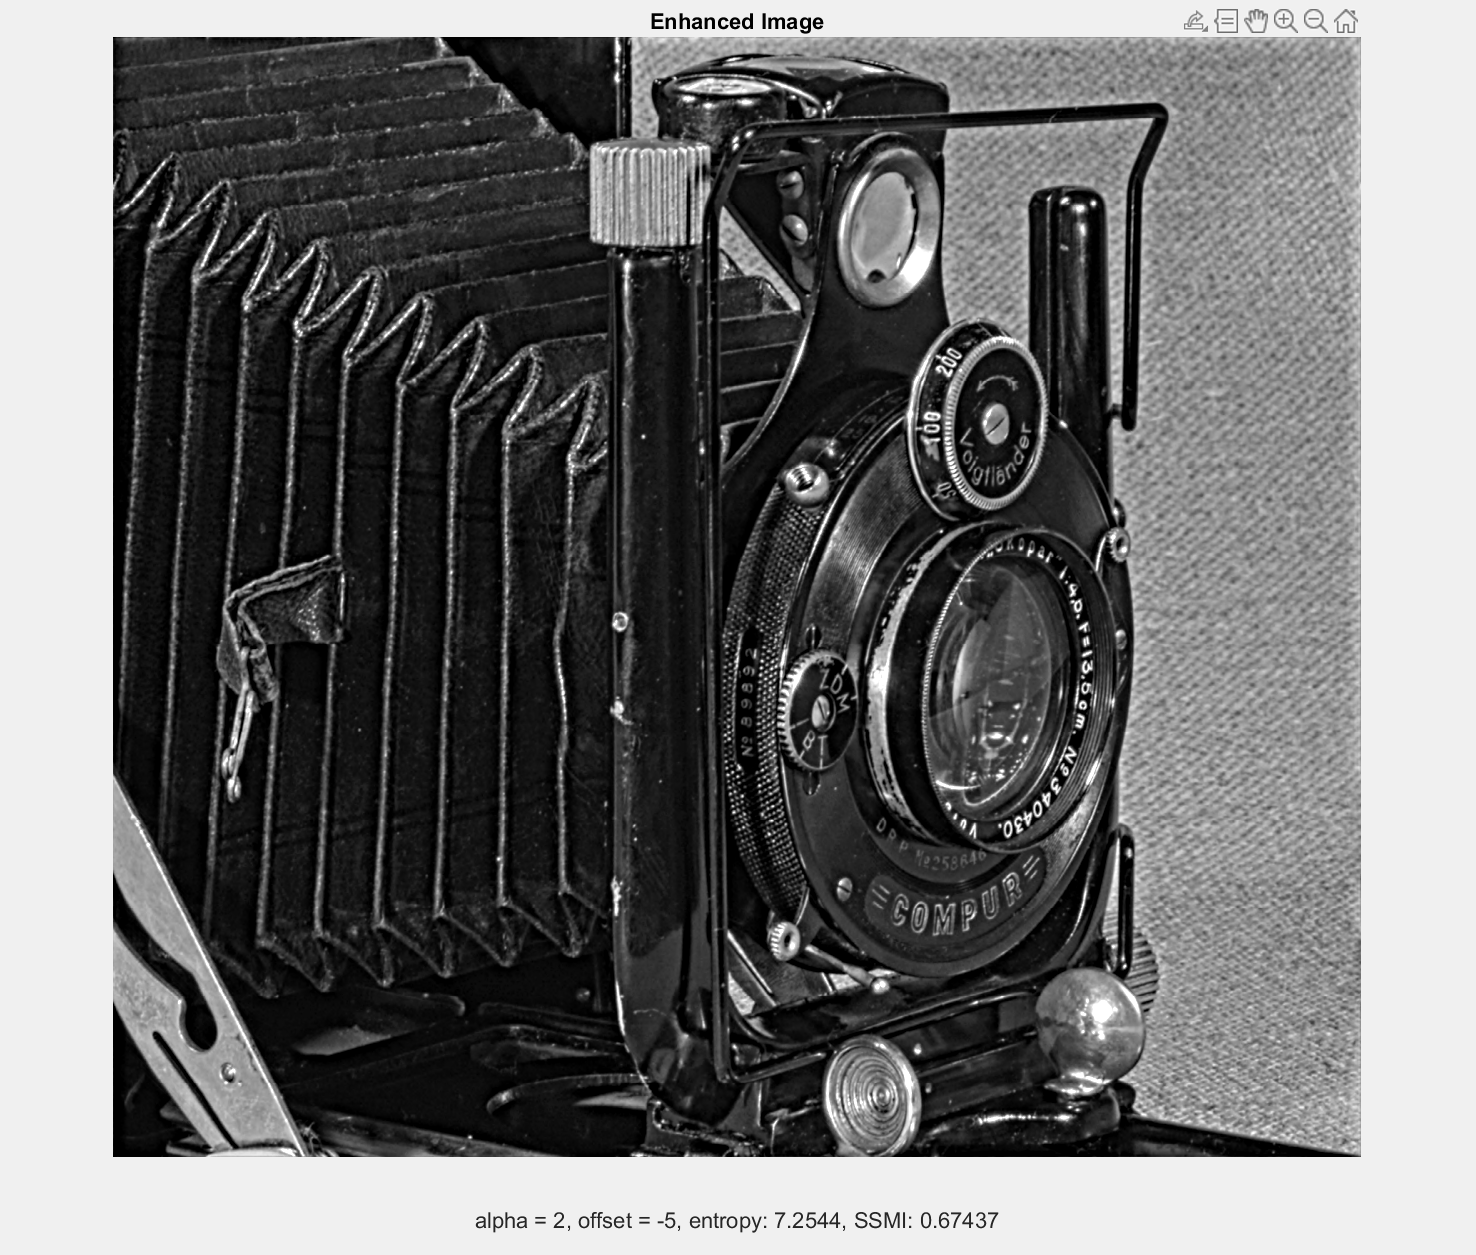


fig2 = figure;
set(gcf,'Visible','on')
% fig2.Position(3:4) = [w-mod(w,16), h-mod(h,16)];
imshow(uint8(enhanced), [0 255])
title('Enhanced Image')
xlabel(['alpha = ' num2str(alpha) ', brightness = ' num2str(brightness) [', entropy: ' num2str(entropy(uint8(enhanced))) ', SSMI: ' num2str(ssim(uint8(enhanced),uint8(image)))]])